Wc=tf([10115 7590 42],[198062 159339 31709 344 0.96],'var','p')

Wc =
 
               10115 p^2 + 7590 p + 42
  --------------------------------------------------
  198062 p^4 + 159339 p^3 + 31709 p^2 + 344 p + 0.96
 
Continuous-time transfer function.
Model Properties


ans = 'k =0.005 Ti =20 k/Ti =0.00025'

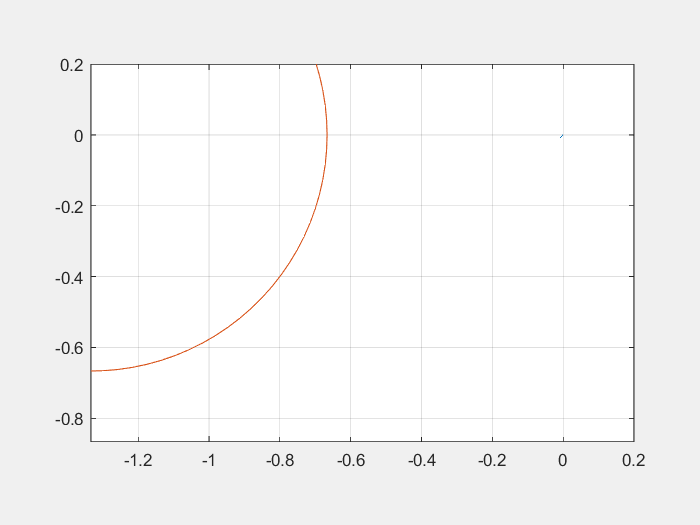


rotach(Wc, 0.005, 20, 2);

% Інтерполяція
k = 0.8:0.1:1.5;                 
Ti = [19.5, 21.5, 24, 28, 33, 43, 58, 100];  
k0 = k ./ Ti;                
k_interp = 0.8:0.1:1.5;          
k_1 = interp1(k, k0, k_interp, 'linear'); 
k0_1 = interp1(k, k0, k_interp, 'linear'); 

plot(k, k0,'.', k_interp, k_1, '-'); 
hold on
plot(k(3), k0(3), '*','LineWidth',3);
grid on;
xlabel('k');
ylabel('k0 = k/Ti');
legend('Початкові дані', 'Інтерпольовані дані');
hold off;

% Інтерполяція
k = 0.8:0.1:1.5;                 
Ti = [19.5, 21.5, 24, 28, 33, 43, 58, 100];  
k0 = k ./ Ti;                
k_interp = 0.8:0.1:1.5;          
k_1 = interp1(k, k0, k_interp, 'linear'); 
k0_1 = interp1(k, k0, k_interp, 'linear'); 

plot(k, k0,'.', k_interp, k_1, '-'); 
hold on
plot(k(3), k0(3), '*','LineWidth',3);
grid on;
xlabel('k');
ylabel('k0 = k/Ti');
legend('Початкові дані', 'Інтерпольовані дані');
hold off;

% Перехідні характеристики
% 1) Метод М-кола
% k = 1; 
% Ti = 24;
% Wpi_m = k*tf([Ti 1], [Ti 0])
% Wc_m = (Wc * Wpi_m) / (1 + Wc * Wpi_m);  
% 
% step(Wc_m);
% xlim([0 100]);
% grid on

% 2) CST

% Wpi_cst = tf(C)
% Wpi_cst = tf([1.524 0.007206], [1 0])
% Wc_cst = (Wc * Wpi_cst) / (1 + Wc * Wpi_cst);  
% step(Wc_cst);
% grid on
% xlim([0 100]);

% step(Wc_m, Wc_cst, '--');
% legend ('На заданий показник коливності', 'PID Tuning')
% grid on
% xlim([0 100]);

% sim('PIDmodelsim.slx', 'SaveOutput', 'on');
% plot(ans.PI_MPC);
% grid on;